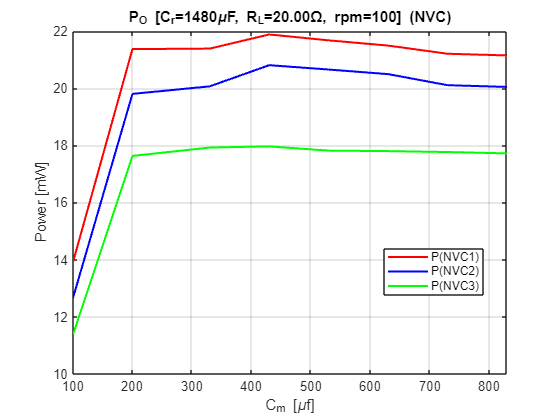


% Dati misurati (NVC1_100rpm.csv, NVC2_100rpm.csv, NVC3_100rpm.csv - tabella "R = 20 Ohm"):
% sweep del condensatore di compensazione C_m, R_L e rpm fissi.
% NOTA: i valori di potenza di NVC1 in questo file vanno divisi per 10
% (indicazione riportata esplicitamente nel CSV originale).
% CORREZIONE NVC3 a C_m=100uF: il CSV originale riportava Po=17.6321 mW, Pi=27.5764 mW,
% quasi identici al punto C_m=200uF (probabile duplicazione/errore di trascrizione, dato
% che NVC1 e NVC2 mostrano entrambi un salto netto tra C_m=100 e C_m=200uF). Valore
% sostituito con una stima ottenuta applicando a NVC3 il rapporto medio Po100/Po200 e
% Pi100/Pi200 osservato in NVC1 e NVC2 (rapporto Po ~0.6454, rapporto Pi ~0.7338).

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 20;           % Ohm - carico fisso durante lo sweep
rpm_b1 = 100;       % rpm fisso durante lo sweep

C_L = [100 200 330 430 530 630 730 830]*1e-6;   % F - condensatore di compensazione C_m (asse x)

Po_b1_mW = [139.166 213.671 213.847 218.787 216.728 214.902 212.041 211.455]/10;
Pi_b1_mW = [243.533 329.446 331.023 331.352 330.905 319.846 314.907 315.241]/10;

Po_b2_mW = [12.6604 19.7995 20.0635 20.8041 20.6520 20.4918 20.1045 20.0428];
Pi_b2_mW = [22.8491 31.3655 31.5957 31.8600 31.3682 31.3654 30.7472 30.3613];

Po_b3_mW = [11.3783 17.6306 17.9221 17.9640 17.8153 17.7979 17.7662 17.7182];   % C=100uF stimato (CSV: 17.6321, anomalo)
Pi_b3_mW = [20.2027 27.5297 27.7423 27.3399 27.4494 27.4269 27.4202 27.0349];   % C=100uF stimato (CSV: 27.5764, anomalo)

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;
P_real_b3 = Po_b3_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;
P_in_b3 = Pi_b3_mW/1000;


figure;
plot(C_L*1e6, P_real_b1*1000, 'r-', 'LineWidth', 1.5);hold on;
plot(C_L*1e6, P_real_b2*1000, 'b-', 'LineWidth', 1.5);
plot(C_L*1e6, P_real_b3*1000, 'g-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (NVC)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
legend(["P(NVC1)", "P(NVC2)", "P(NVC3)"], "Location", "best")
hold off;

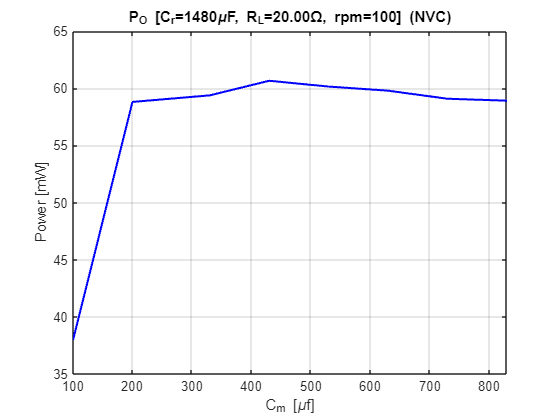



figure;
plot(C_L*1e6, (P_real_b1+P_real_b2+P_real_b3)*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (NVC)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
hold off;